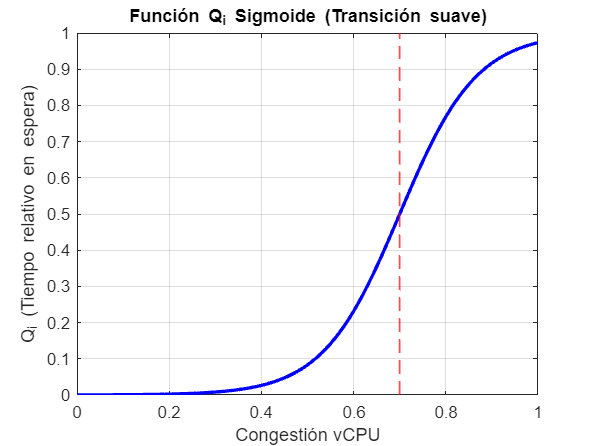

% Graficar sigmoide: Q

a = 12; %pendiente
b = 0.7; % punto de inflexión (a partir de 70% es congestión crítica)
x = 0:0.01:1; %array de [0,1] que representa los diferentes valores de congestión en vcpu

sigmoide_function = 1./(1+exp(-a*(x-b)));

%Graficamos sigmoide
figure;
plot(x, sigmoide_function, "b","LineWidth",2);
hold on
xline(b, "r--", "LineWidth", 1); % La intersección entre gráficas es el punto de inflexión
hold off
grid on;
xlabel("Congestión vCPU")
ylabel("Q_i (Tiempo relativo en espera)")
title("Función Q_i Sigmoide (Transición suave)")
xlim([0 1]);
ylim([0 1]);